# Initialisation


clc; 
clear; 
close all;

## Paramètres généraux

Ns = 5000;       % Nombre de symboles
Ds = 1e6;        % Débit symbole (1 Msymboles/s)
Fse = 4;         % Facteur de suréchantillonnage
Fe = Ds*Fse;     % Fréquence d'échantillonnage (4 MHz)
rolloff = 0.35;  % Rolloff pour le RRC
SPAN = 8;        % Nombre de périodes symboliques pour le RRC

## Développement du canal

Generation des bits QPSK

bits = randi([0 1], 2*Ns, 1); 
% mapping de gray
symI = 1-2*bits(1:2:end);
symQ = 1-2*bits(2:2:end);
symboles = (symI + 1j*symQ)/sqrt(2);  % Normalisation d'énergie = 1

Filtre d'émission RRC

% Filtre en racine de cosinus surélevé : on utilise rcosdesign
h_rrc = rcosdesign(rolloff, SPAN, Fse, 'sqrt');

% Suréchantillonnage
x_up = upsample(symboles, Fse);

% Convolution avec le filtre RRC (émission)
x_emis = conv(x_up, h_rrc, 'same');


Définition des cas de canal à tester

% Format {alpha_ch, d_ch, phi_ch}
canaux = {
    {1.0, 1, 0},      % Cas 1
    {1.0, 4, 0},      % Cas 2
    {1.0, 1, pi/4},   % Cas 3
    {0.5, 1, 0},      % Cas 4
    {0.5, 4, 0}       % Cas 5
};


Boucle sur les différents cas de canal

for cas_num = 1:length(canaux)
    
    % Récupération des paramètres pour ce cas
    alpha_ch = canaux{cas_num}{1};
    d_ch     = canaux{cas_num}{2};
    phi_ch   = canaux{cas_num}{3};
    
    % Construction du canal (et optionnellement, affichage)
    h_canal = create_canal(alpha_ch, d_ch, phi_ch);
    
    % On peut visualiser le canal si on veut
    % plot_canal(h_canal, cas_num);   % <-- décommenter si besoin

    %% 4.1) Convolution avec le canal
    y_canal = conv(x_emis, h_canal, 'full');
    
    %% 4.2) Filtre de réception RRC
    % On suppose gRx = h_rrc (même filtre)
    gRx = h_rrc; 
    y_rec = conv(y_canal, gRx, 'full');

    Échantillonnage

    % Le retard introduit par 2 filtres RRC vaut environ SPAN*Fse/2 + SPAN*Fse/2 = SPAN*Fse
    offset = SPAN * Fse;  
    nIdx   = offset + (0:Ns-1)*Fse;
    nIdx   = nIdx(nIdx <= length(y_rec));  % éviter dépassement
    y_sym  = y_rec(nIdx);
    

Affichage de la constellation pour ce cas

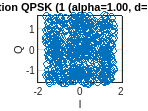

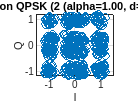

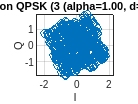

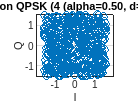

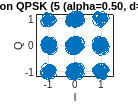

    figure;
    plot(real(y_sym(1:500)), imag(y_sym(1:500)), 'o');
    axis equal; grid on;
    xlabel('I'); ylabel('Q');
    titre = sprintf('Constellation QPSK (%d (alpha=%.2f, d=%d, phi=%.2f))', ...
        cas_num, alpha_ch, d_ch, phi_ch);
    title(titre);
    
end

La forme des constellations est due aux interferences, vu qu'il y a plusieurs signaux ça crée des interférences qui vont "grossir" nos symbôles

plus le retard ( ou délai de propagation ) d est grand, plus le canal est sélectif en fréquence, donc plus il distord le signal.

impact de alpha et phi: ils déterminent la profondeur et la position des creux dans la réponse en fréquence, donc la sélectivité, et la rotation de la constellation en sortie. Un alpha élevé crée une constellation plus concentrée, tandis qu'un alpha faible cause une dispersion et un flux de symboles. Le décalage en phase phi déplace symplement le symbole dans une direction circulaire.

Ainsi sans égalisation, la constellation est dégradée. L’égaliseur (ZF, MMSE) permettra de retrouver 4 nuages QPSK compacts.

## Egalisation

 % Égalisation ZF
    P = 10; % Changez cette valeur selon le cas
    [y_eq_ZF, ~] = equalize_ZF(y_sym, symboles, P);
    
    % Affichage de la constellation après égalisation ZF
    figure;
    plot(real(y_eq_ZF(1:500)), imag(y_eq_ZF(1:500)), 'o');
    axis equal; grid on;
    xlabel('I'); ylabel('Q');
    title(sprintf('Constellation après égalisation ZF QPSK (%d (alpha=%.2f, d=%d, phi=%.2f))', ...
        cas_num, alpha_ch, d_ch, phi_ch));
    
    % Égalisation MMSE
    [y_eq_MMSE, ~] = equalize_MMSE(y_sym, symboles, P, 10); 
    % Affichage de la constellation après égalisation MMSE
    figure;
    plot(real(y_eq_MMSE(1:500)), imag(y_eq_MMSE(1:500)), 'o');
    axis equal; grid on;
    xlabel('I'); ylabel('Q');
    title(sprintf('Constellation après égalisation MMSE QPSK (%d (alpha=%.2f, d=%d, phi=%.2f))', ...
        cas_num, alpha_ch, d_ch, phi_ch));
    
end

SNR_values = 0:1:30;  % Plage des SNR à tester
BER_ZF = zeros(size(SNR_values));
BER_MMSE = zeros(size(SNR_values));


% Affichage de la courbe de la probabilité d'erreur binaire (BER)
figure;
semilogy(SNR_values, BER_ZF, 'r', 'LineWidth', 2);
hold on;
semilogy(SNR_values, BER_MMSE, 'b', 'LineWidth', 2);
grid on;
xlabel('SNR (dB)');
ylabel('Probabilité d\'erreur binaire');
legend('ZF', 'MMSE');
title('Comparaison de la probabilité d\'erreur binaire en fonction du SNR');